clc; clear; close all
[filepath,~,~] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(filepath);
addpath(fullfile(filepath,'myfunc'),'-begin');

## Generate Simulation data points


% define data points
sigma = [1,2;1,1.5;2,4]; % var of principal components for each data set
rot = [-10,20,-45]; % data sets rotation
n = [1000,2000,1500]; % number of each dataset
mu = [1,4;6,5;0,10]'; % mean of each data set


k = 3; % define ellips, 3 sigma, 99.7% of the data within the ellip
n_pt = 100; % 100 points on ellip

% data and ellip
dim = size(mu,1);
O = cell(length(n),1);
ellips_ref = NaN(dim,n_pt,length(n));
for i = 1:length(n)
    s = rotcov(diag(sigma(i,:)),rot(i)); % rotated cov matrix
    O{i} = randn1(s,n(i),mu(:,i)); % rotated data
    ellips_ref(:,:,i) = cov2ellip(s,k,mu(:,i),n_pt); % 3 sigma ellip
end

% color for ploting
cl1 = [0 0.4470 0.7410;0.8500 0.3250 0.0980;1 0.85 0.1];
cl2 = [0 0 1;1 0 0;0.9290 0.6940 0.1250];

## Plot data

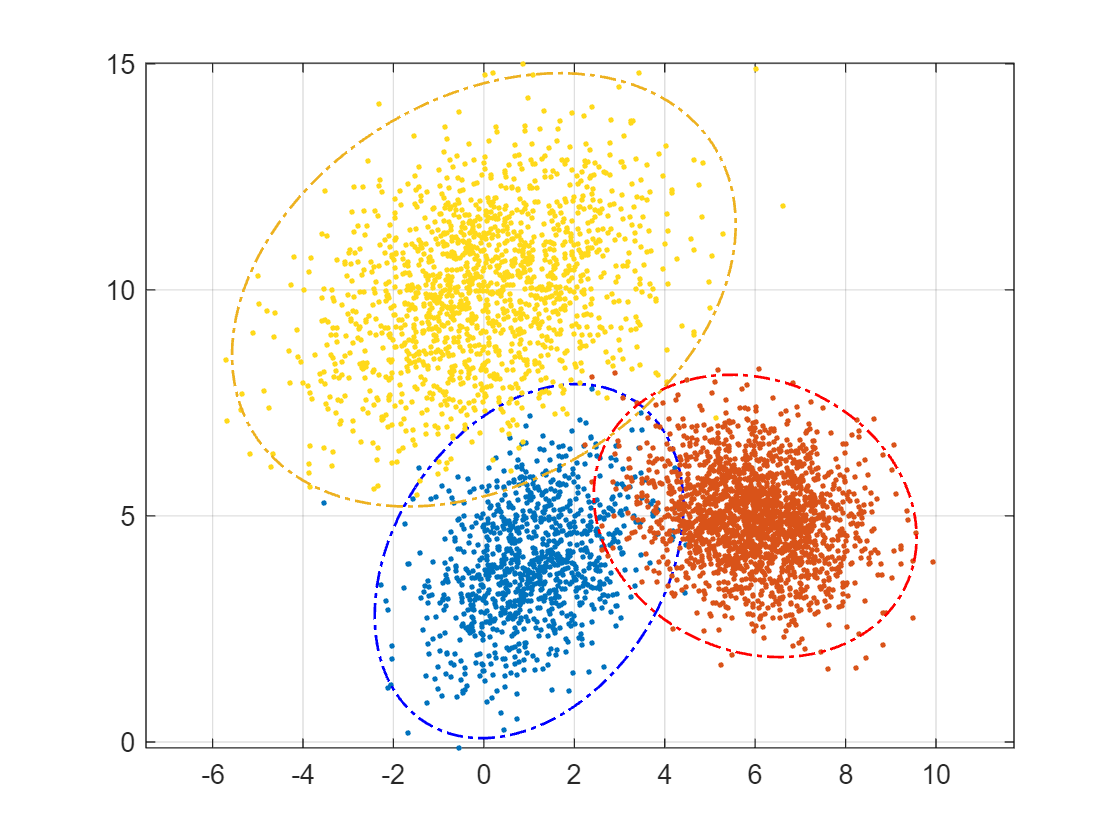

figure
for i = 1:length(n)
    plot(O{i}(1,:),O{i}(2,:),'.','Color',cl1(i,:)); hold on
    plot(ellips_ref(1,:,i),ellips_ref(2,:,i),'-.','Color',cl2(i,:),'LineWidth',1); hold on
end
grid on; axis equal

## prepare testing data

O = cell2mat(O'); % mix 3 sets
clearvars -except O ellips_ref cl1 cl2

## Initial Guess Good

p_k0 = [0.1,0.1,0.3]'; % [P(blue), P(red), P(yellow)]
m0 = [0,0;8,2;6,10]'; % mean of 3 sets
s0(:,:,3) = eye(2); % cov matrix
s0(:,:,2) = eye(2)/10;
s0(:,:,1) = eye(2)/10;

## Initial Guess Bad

% p_k0 = [0.1,0.1,0.3]'; 
% m0 = [0,0;1,1;2,2]'; 
% s0(:,:,3) = eye(2); % cov matrix
% s0(:,:,2) = eye(2);
% s0(:,:,1) = eye(2);

maxiter = 200; % max allowed iteration
tol = 1e-4;

## EM for Gaussian Mixtures

iter:   6 ~ 10 | change =   4.329e-02
iter:  16 ~ 20 | change =   1.263e-02
iter:  23 ~ 27 | change =   3.978e-05


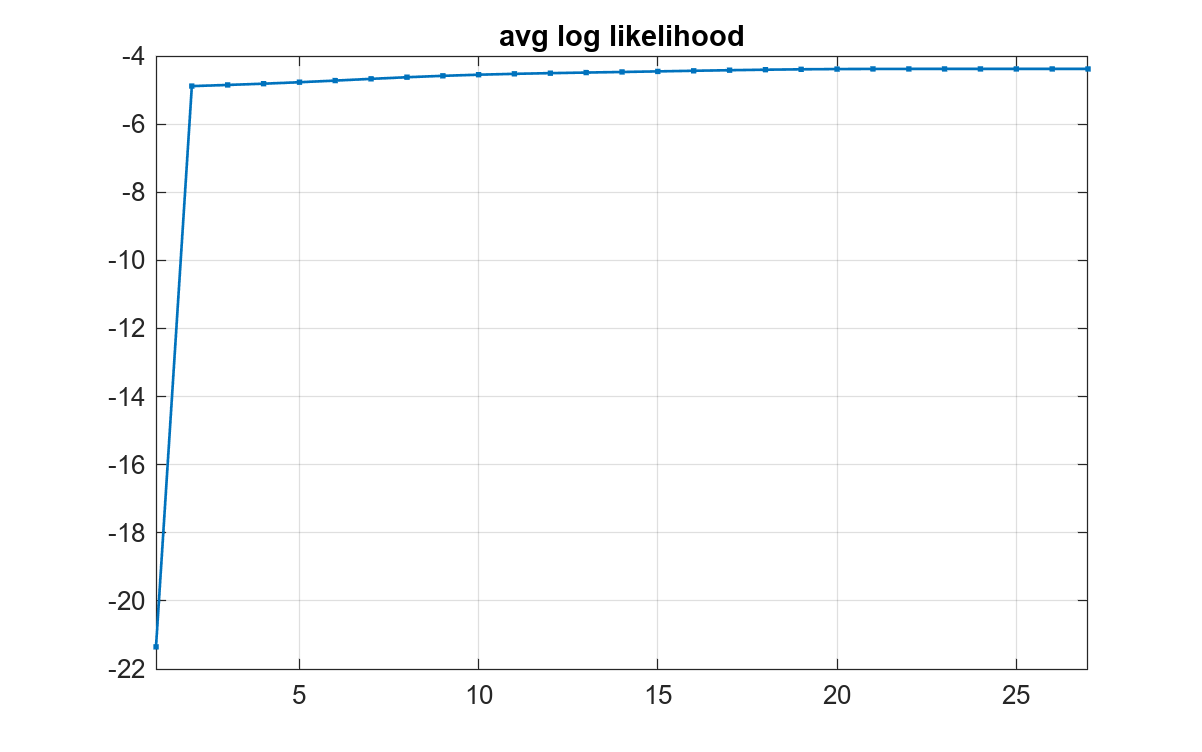

gm = emfit(O,m0,s0,p_k0,'maxiter',maxiter,'tol',tol,'alldata',true);

[m,s,p_k,m_all,s_all,pk_all] = deal(gm.m,gm.s,gm.p_k,gm.m_all,gm.s_all,gm.pk_all);

## Plot results

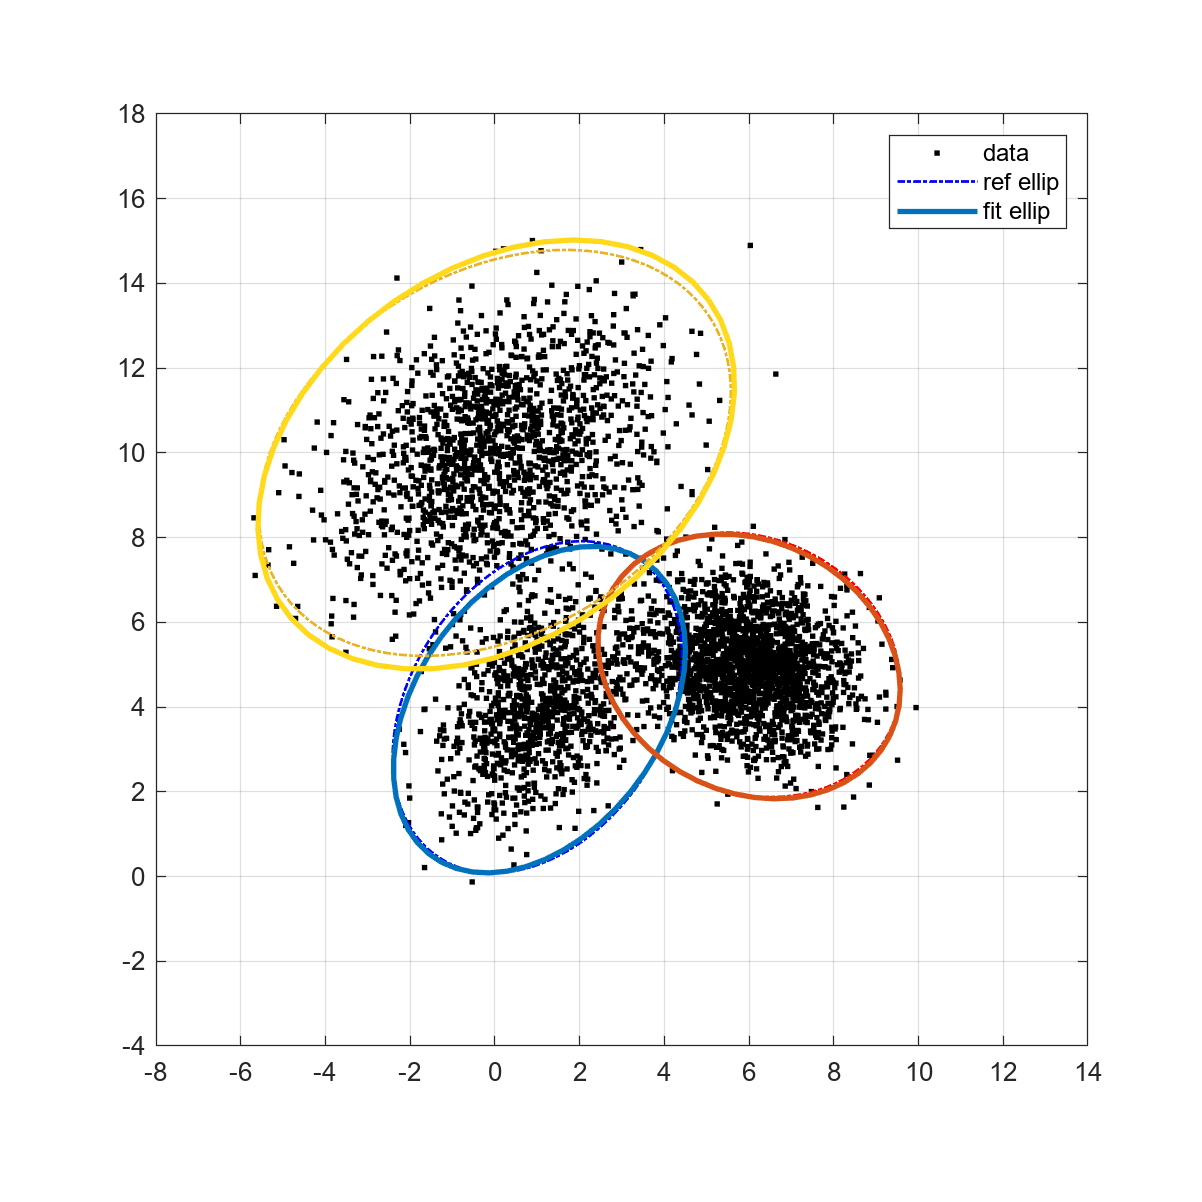

[dim,n_set] = size(m0);
k = 3; % 3 sigma circle
n_pt = 50; % 50 pts on a ellip

f = figure;
po = plot(O(1,:),O(2,:),'.k'); hold on
pp = gobjects(n_set,1); % initialize plots
p0 = plot3(nan,nan,nan);
for i = 1:n_set
    plot(ellips_ref(1,:,i),ellips_ref(2,:,i),'-.','Color',cl2(i,:),'LineWidth',1); hold on
    ellip = cov2ellip(s_all(:,:,i,1),k,m_all(:,1,i),n_pt); % 3 sigma ellip
    pp(i) = plot(ellip(1,:),ellip(2,:),'-','LineWidth',2,...
        'Color',cl1(i,:)); hold on
end
grid on; axis equal
xlim([-8,14]); ylim([-4,18])
pr = plot(nan,nan,'-.','Color',cl2(1,:),'LineWidth',1); hold on
pe = plot(nan,nan,'-','Color',cl1(1,:),'LineWidth',2); hold on
legend([po,pr,pe],{'data','ref ellip','fit ellip'})
set(f,'Units','normalized','Position',[0.25,0.08,0.5,0.8])
drawnow
pause(1)

% update plots
for ii = 1:size(m_all,2)
    for i = 1:n_set
        ellip = cov2ellip(s_all(:,:,i,ii),k,m_all(:,ii,i),n_pt);
        pp(i).XData = ellip(1,:);
        pp(i).YData = ellip(2,:);
    end
    if ii == 1
        for j = 1:20
            p0.XData = nan;
            drawnow
        end
    end
    drawnow
end